Load in data from the work space

 load("loadInData.mat");
data = loadInData;

|==========================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              | Initializer  | nitializer   |                       |
|==========================================================================================================================================================================|
|    1 | Best   |      5.7327 |     0.63029 |      5.7327 |      5.7327 |         none |         true |      0.14081 |           he |        zeros |  5                    |
|    2 | Accept |      6.1225 |      422.74 |      5.7327 |      5.7482 |      sigmoid |        false |   3.8991e-06 |           he |  

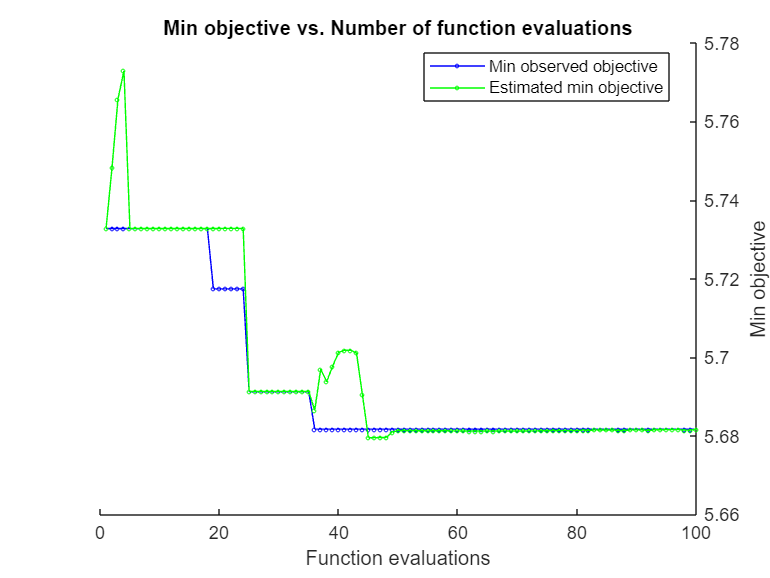


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 6905.3668 seconds
Total objective function evaluation time: 6800.3786

Best observed feasible point:
    Activations    Standardize      Lambda      LayerWeightsInitializer    LayerBiasesInitializer    LayerSizes
    ___________    ___________    __________    _______________________    ______________________    __________

       relu           true        2.5883e-06            glorot                      ones                162    

Observed objective function value = 5.6817
Estimated objective function value = 5.6816
Function evaluation time = 72.3275

Best estimated feasible point (according to models):
    <


electrical_load = data.AC;

% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [data.AC(1:end-1) data.wrkHr(1:end-1)];

T = data.AC(2:end);
% 
% for i = 1:(n -  1)
%     idx=1+(i-1)*input_window_size;
%     X(:,i) =  electrical_load(idx:idx + input_window_size - 1)';
%     T(:,i) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
% end


% Split data into training and testing sets
train_ratio = 0.7;
num_train = floor(length(X) * train_ratio);
X_train = X(1:num_train,:);
T_train = T(1:num_train);
X_test = X(num_train+1:end,:);
T_test = T(num_train+1:end);

% Create and Train Neural Network

opt = struct("ShowPlots",true,"MaxObjectiveEvaluations",70);

net = fitrnet(X_train, T_train,"OptimizeHyperparameters","all","HyperparameterOptimizationOptions", opt);

timeStep= 1;
for j = 1:(floor(length(X_test)/timeStep)-ceil(24/timeStep)-72)
   
    offset = j*timeStep+72 ;
    
    input = X_test(1:offset,:); 
    first_forecast = predict(net, input);
    Yin = first_forecast(end:end);
    Y = zeros(24,2);
    Y(1,:) = [Yin X_test(offset+1,2)];
    
    for i=2:24
        input = [input(2:end,:)' Y(i-1,:)'];
        input = input';
        YNext = predict(net, input);
        Y(i,:)  = [YNext(end:end) X_test(offset+i,2)];

    end
    
    Ypred{j}(:) = Y(:,1);
    Yactual{j}(:) = T_test(offset:offset+23);
end



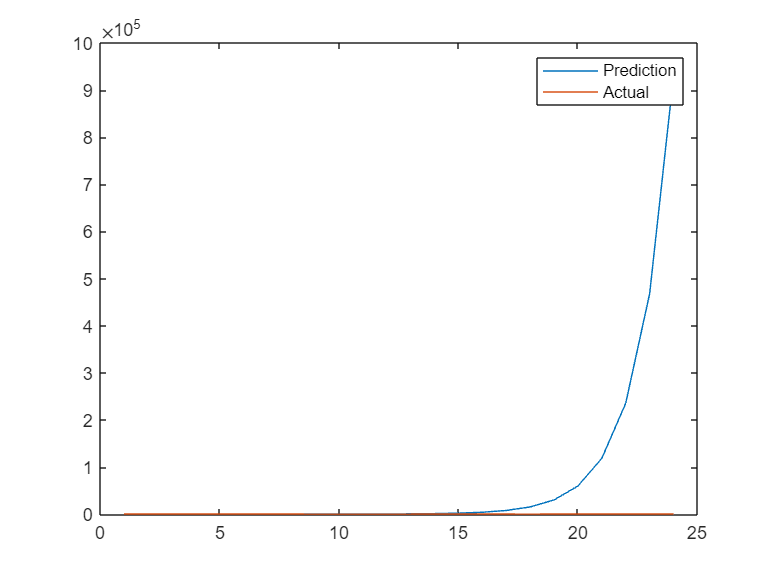

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);

for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;
end

YmapeHr = YmapeHr./j;
Yrmse = sqrt(YseCal./j);



plot(Ypred{1})
hold on
plot(Yactual{1})

hold off
legend("Prediction", "Actual")

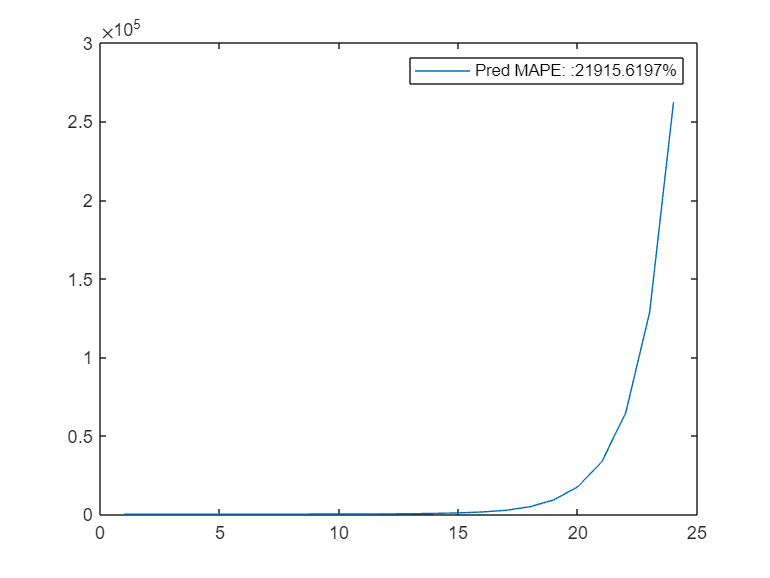



plot(YmapeHr)
legend("Pred MAPE: :" + mean(YmapeHr) +"%")

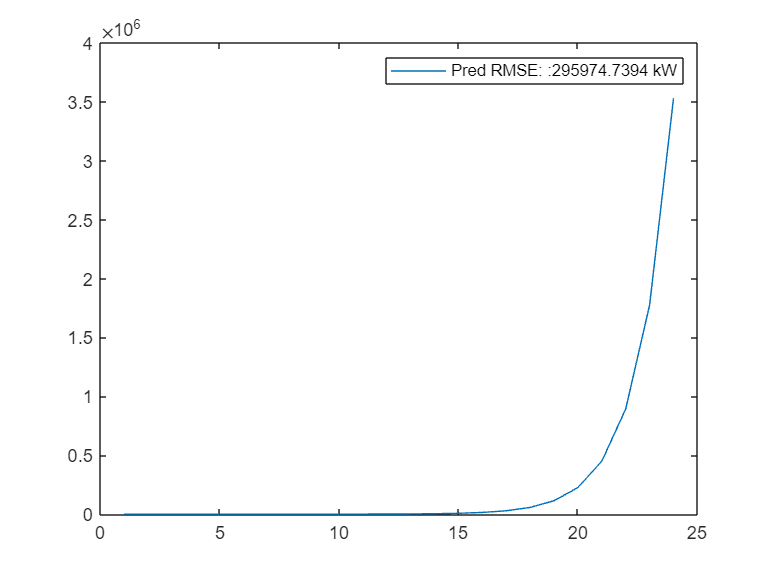


plot(Yrmse)
legend("Pred RMSE: :" + mean(Yrmse) +" kW")